% 1 - 100K
step_SNR = log10(100e3)-log10(1)

step_SNR = 5

stepsize_SNR = (100e3-1)/(step_SNR*10)

stepsize_SNR = 2.0000e+03

frequencies_SNR = logspace(log10(1), log10(100e3), step_SNR*10);

% 1k -10Mhz
step_pwr = log10(10e5)-log10(1e3)

step_pwr = 3

stepsize_pwr = (10e5-1e3)/(step_pwr*10)

stepsize_pwr = 33300

frequencies_pwr = logspace(log10(1), log10(100e3), step_pwr*10);

clearvars
data_07 = readtable('./ADC_Data/11-24-Data-SEDE/2kIN---1MHz-20%/2k_50%_950mv_1M_D0-D7.csv');

data_815 = readtable('./ADC_Data/11-24-Data-SEDE/2kIN---1MHz-20%/2k_50%_950mv_1M_D8-D15.csv');

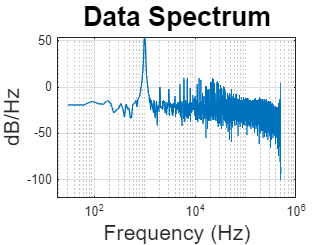


data_07_array = table2array(data_07(2:end,2));
data_815_array = table2array(data_815(2:end,2));


data07_B = dec2bin(data_07_array);
data815_B = dec2bin(data_815_array);
data815_B_C11 = data815_B(:,1);
data815_B_C8 = data815_B(:,4);

data815_B_C11 = str2num(data815_B_C11);
data07_filt = char(32 * ones(size(data07_B)));
data8_filt = char(32 * ones(size(data815_B_C8)));

k = 1;
for i = 1:length(data815_B_C11)
    if data815_B_C11(i,1) == 1
        data07_filt(k,:) = data07_B(i,:);
        data8_filt(k,:) = data815_B_C8(i,:);
        k = k+1;
    end
end
data07_filt = data07_filt(1:k-1,:);
data8_filt = data8_filt(1:k-1,:);
data815_B_C8_shift = bitshift(str2num(data8_filt), 8);
data07_B_shift = bin2dec(data07_filt);
% Combine data1 and data2
result_data = data815_B_C8_shift + data07_B_shift;
% result_data = result(result ~= 0);

Fs=1e6;
num_segments=1;
f_signal =  2e3;
f_s = Fs;
BW =500e3;
sample_size=2^15;
periodogram_length = sample_size / num_segments;
fbin = f_s / periodogram_length;
plotYN = 1; plotAll = 0; plotHold = 0; plotLin = 0; datNorm = 1;
[sinusoid_power, data_minus_sinusoid_in_BW_power, SNDR, ENOB,HD2,HD3, SNR, SFDR] = ...
    plot_periodogram_SFDR(result_data, periodogram_length, num_segments, f_signal, ...
    f_s, BW, plotAll, plotHold, plotYN, plotLin,datNorm);

fprintf('@Freq = %.3f, SNR = %.3f dB, SNDR = %.3f dB, SFDR = %.3f dB, HD2 = %.3f and HD3 = %.3f\n',   f_signal, SNR,SNDR, SFDR, HD2,HD3);

@Freq = 2000.000, SNR = 32.992 dB, SNDR = -53.360 dB, SFDR = -9.251 dB, HD2 = 10.660 and HD3 = -9.251


set(gcf,'color','w')

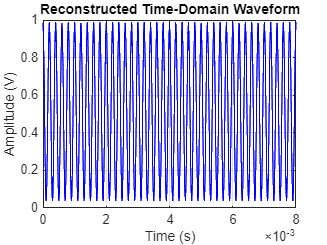


% Parameters
fs = 5e6;                 % Sampling rate in Hz
N = length(result_data);                  % Number of samples
bit_depth = 9;            % ADC bit resolution
V_min = 0;              % Minimum input voltage
V_max = 1;               % Maximum input voltage

% Map codes to voltage
voltages = ((result_data / (2^bit_depth - 1)) * (V_max - V_min)) + V_min;

% Create time axis
t = (0:N-1) / fs;

% Plot the reconstructed waveform
figure;
plot(t, voltages, 'b');
title('Reconstructed Time-Domain Waveform');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;


% Find zero crossings
zero_crossings = find(diff(sign(voltages)) ~= 0.5); % Indices of zero crossings
times = t(zero_crossings);                        % Times of zero crossings

% Calculate period
periods = diff(times);                            % Time intervals between crossings
average_period = mean(periods);                  % Average period
frequency = 1 / average_period;                  % Frequency (Hz)

% Display the result
disp(['Estimated Frequency: ', num2str(frequency/1e3), ' kHz']);

Estimated Frequency: 5000 kHz
